# Señales y sistemas

## Señales continuas y discretas :D

Señal continua: x(t)

Señal discreta: x[n]

**Handles vs symbolic**

syms t

%Variable simbólica
y_symb=cos(t)

$$y\_symb = \cos\left(t\right)$$


subs(y_symb,t,[5 8 10]) %queremos evaluara t

$$ans = \left(\begin{array}{ccc} \cos\left(5\right) & \cos\left(8\right) & \cos\left(10\right) \end{array}\right)$$


% function handle 
%@ para indicar que depende de esa variable
y_fh=@(t) cos(t)

y_fh = function_handle with value:
    @(t)cos(t)



%Se puede hacer álgebra con variables simbólicas
y_3=y_symb+sin(t)+exp(-t)

$$y\_3 = {\mathrm{e}}^{-t}+\cos\left(t\right)+\sin\left(t\right)$$


%y_fh+y_fh error: no se pueden hacer operaciones con las function handles

% Functions handle se evalúan más rápido 
% En simbólicas es más tardado

y_3_fh=matlabFunction(y_3)

y_3_fh = function_handle with value:
    @(t)exp(-t)+cos(t)+sin(t)


y_3_fh([5 8 10])

ans =    -0.6685    0.8442   -1.3830



% Diferencia entre variables simbólicas y función handle
y_fh([5 8 10])

ans =     0.2837   -0.1455   -0.8391


%y_symb([5 8 10]) error: No se evalúan directamente

diff(y_3) % da la derivada

$$ans = \cos\left(t\right)-{\mathrm{e}}^{-t}-\sin\left(t\right)$$

vpa(int(y_3,[0 1])) % vpa para que lo evalúe con números

$$ans = 1.9332892377683144676560419440259$$

%también puede ser con double() o eval()

int(y_3,t)

$$ans = -{\mathrm{e}}^{-t}-\sqrt{2}\,\cos\left(t+\frac{\pi }{4}\right)$$

int(y_3,[0 1])

$$ans = \sin\left(1\right)-{\mathrm{e}}^{-1}-\cos\left(1\right)+2$$

**Continuas vs discretas**

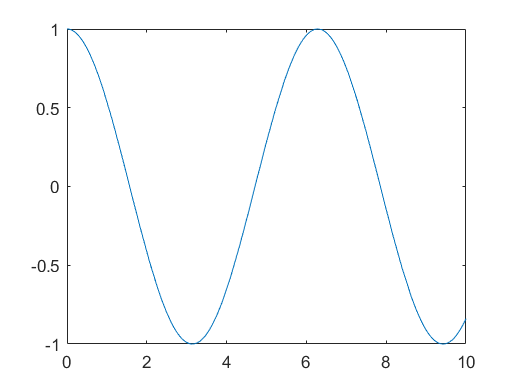

% fplot es para funciones simbólicas 
% y para "function handles"
figure
fplot(y_symb,[0 10]) 


figure
fplot(y_fh,[0 10])


%";" al final suprime la salida en los resultados
t_disc=0:10;

% y discreta evaluada
y_disc=y_fh(t_disc)

y_disc =     1.0000    0.5403   -0.4161   -0.9900   -0.6536    0.2837    0.9602    0.7539   -0.1455   -0.9111   -0.8391


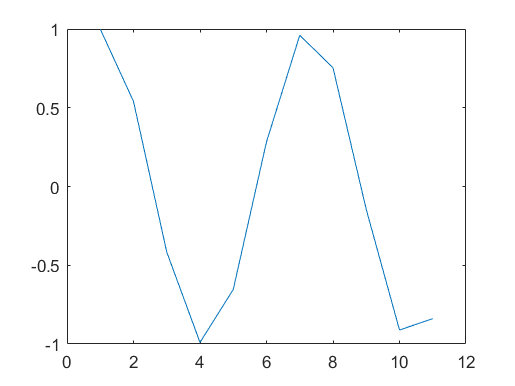


figure
%plot es para muestras o vectores
plot(y_disc)

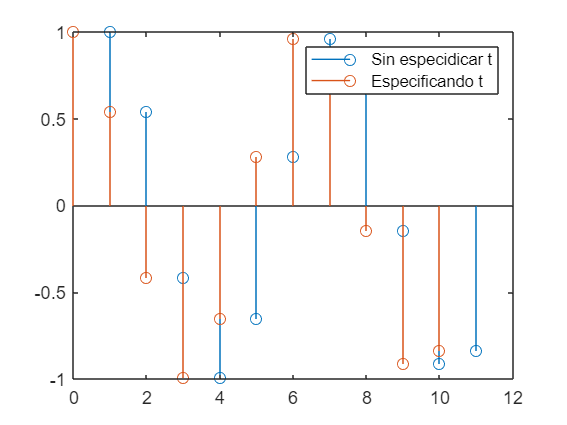


%con stem también es para muestras o vectores y te muestra bien el cero y
%donde emerge la muestra
figure
stem(y_disc) % lo hace a partir de la muestra 1 y no desde cero, porque no pusimos el x
hold on
stem(t_disc,y_disc) %este es el bueno porque está centrado en cero
hold off
legend("Sin especidicar t","Especificando t")


t_disc=0:0.1:10;
y_disc=y_fh(t_disc)

y_disc =     1.0000    0.9950    0.9801    0.9553    0.9211    0.8776    0.8253    0.7648    0.6967    0.6216    0.5403    0.4536    0.3624    0.2675    0.1700    0.0707   -0.0292   -0.1288   -0.2272   -0.3233   -0.4161   -0.5048   -0.5885   -0.6663   -0.7374   -0.8011   -0.8569   -0.9041   -0.9422   -0.9710   -0.9900   -0.9991   -0.9983   -0.9875   -0.9668   -0.9365   -0.8968   -0.8481   -0.7910   -0.7259   -0.6536   -0.5748   -0.4903   -0.4008   -0.3073   -0.2108   -0.1122   -0.0124    0.0875    0.1865


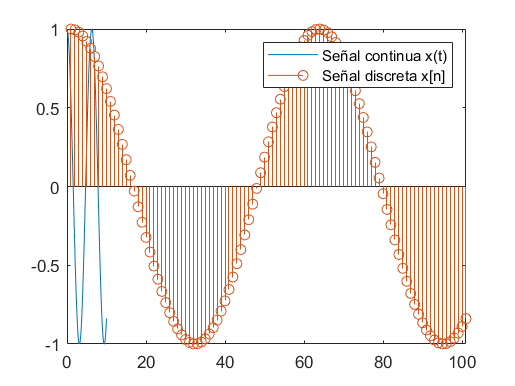

fplot(y_fh,[0 10])
hold on
stem(y_disc)
hold off
legend("Señal continua x(t)", "Señal discreta x[n]") %n número de muestras

**Señal continua y discreta **


$$x\left(t\right)=3e^{0\ldotp 4t} ,y\left(t\right)=2e^{-0\ldotp 9t} ,-2\le t\le 5$$


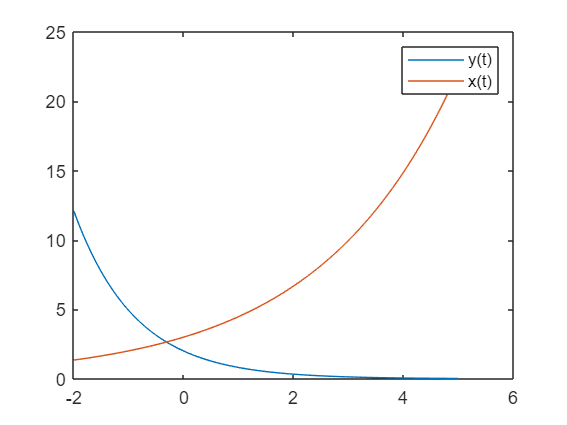

t_1=-2:0.1:5;
x_1=3*exp(0.4*t_1);
y_1=2*exp(-0.9*t_1);

figure
plot(t_1,y_1)
hold on
plot(t_1,x_1)
hold off
legend("y(t)","x(t)")

**Ejemplo clase**

$x\left(t\right)=\cos \left(t\right)+\sin \left(3t\right)$ en tres periodos

t_2= 0:0.1:19

t_2 =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


% anadí un offset de 10
x_2=cos(t_2)+sin(3*t_2)+10

x_2 =    11.0000   11.2905   11.5447   11.7387   11.8531   11.8751   11.7992   11.6281   11.3722   11.0490   10.6814   10.2959    9.9198    9.5797    9.2984    9.0932    8.9746    8.9453    9.0000    9.1260    9.3044    9.5120    9.7230    9.9122   10.0563   10.1369   10.1417   10.0658    9.9124    9.6920    9.4221    9.1253    8.8274    8.5550    8.3333    8.1838    8.1223    8.1573    8.2897    8.5121    8.8098    9.1619    9.5434    9.9267   10.2847   10.5930   10.8315   10.9869   11.0532   11.0323


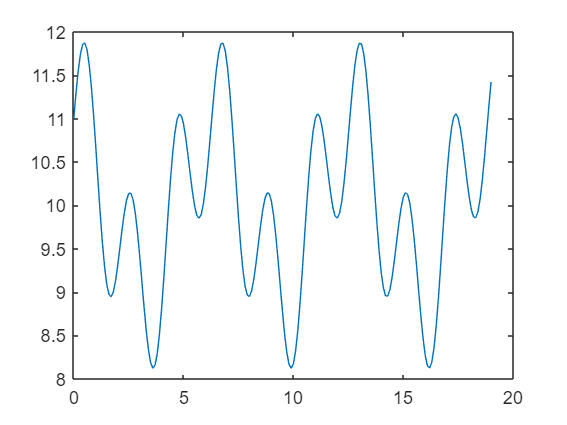

plot(t_2,x_2)

**Formas de ondas básicas**

syms t
a=1.5;
b=2.2;
x(t) = cos(a*t)+sin(b*t)

$$x(t) = \cos\left(\frac{3\,t}{2}\right)+\sin\left(\frac{11\,t}{5}\right)$$

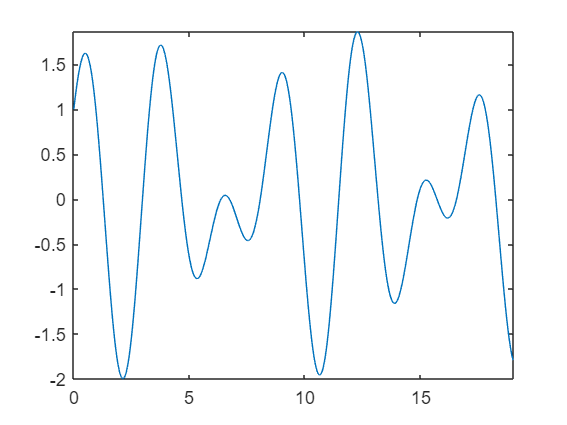

figure
fplot(x,[0 19])

**Ejemplo **

Sinusoidal decayendo


$$x\left(t\right)={\textrm{Ce}}^{\textrm{rt}} \cos \left(w_o t+\theta \;\right),r<0$$


t=[0 1], theta = 5, omega_0=5, C=1, r=3

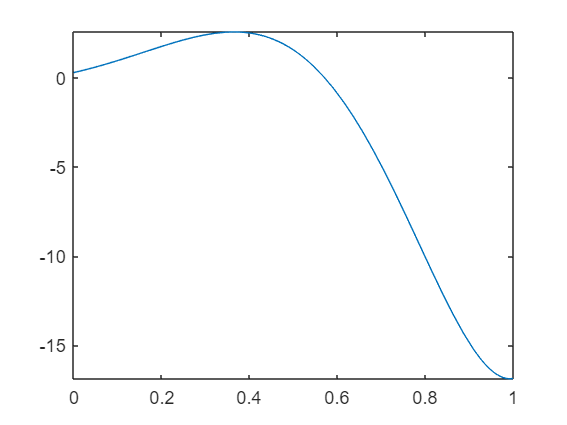

syms t_3
theta=5;
C=1;
w_0=5;
r=3;
x_3=C*exp(r*t_3)*cos(w_0*t_3+theta);
figure
fplot(x_3,[0 1])